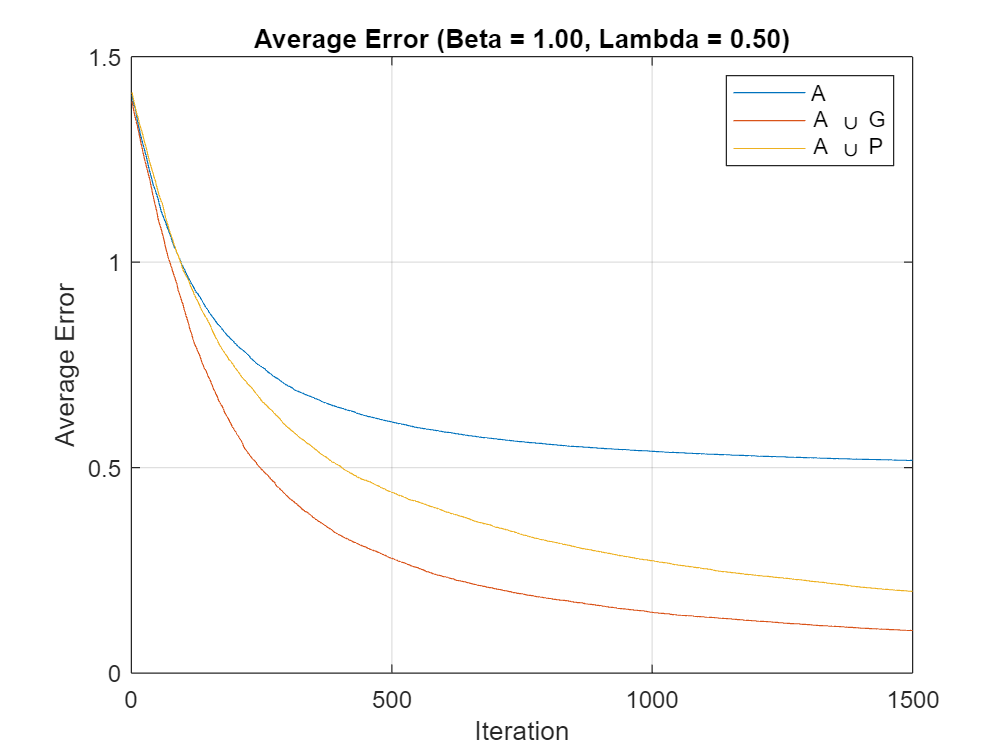

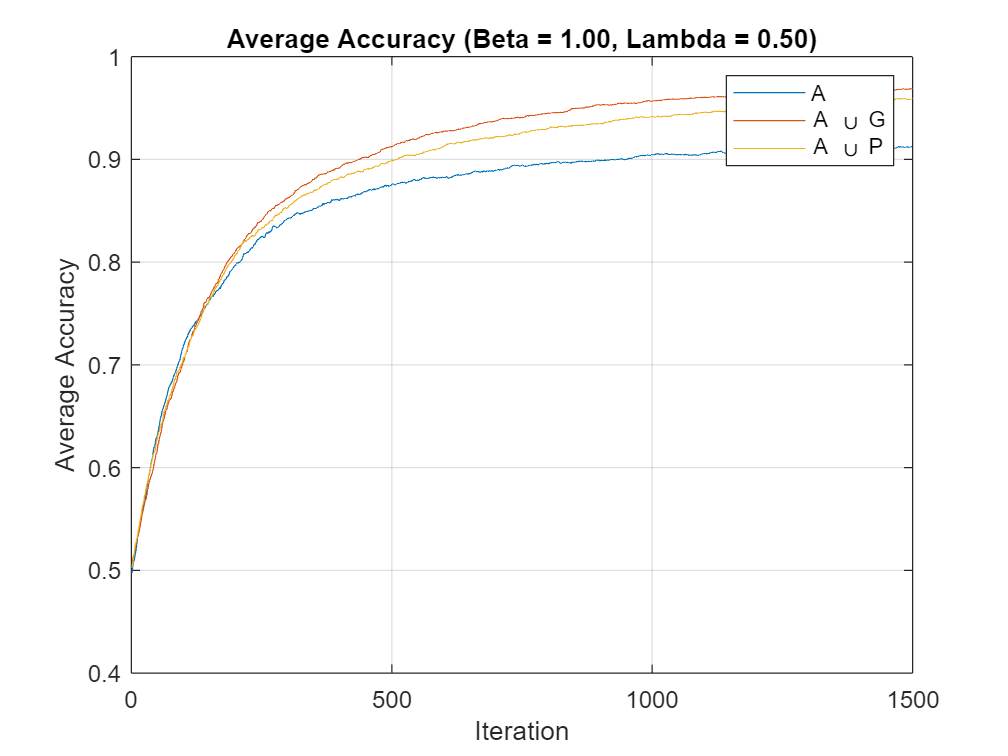

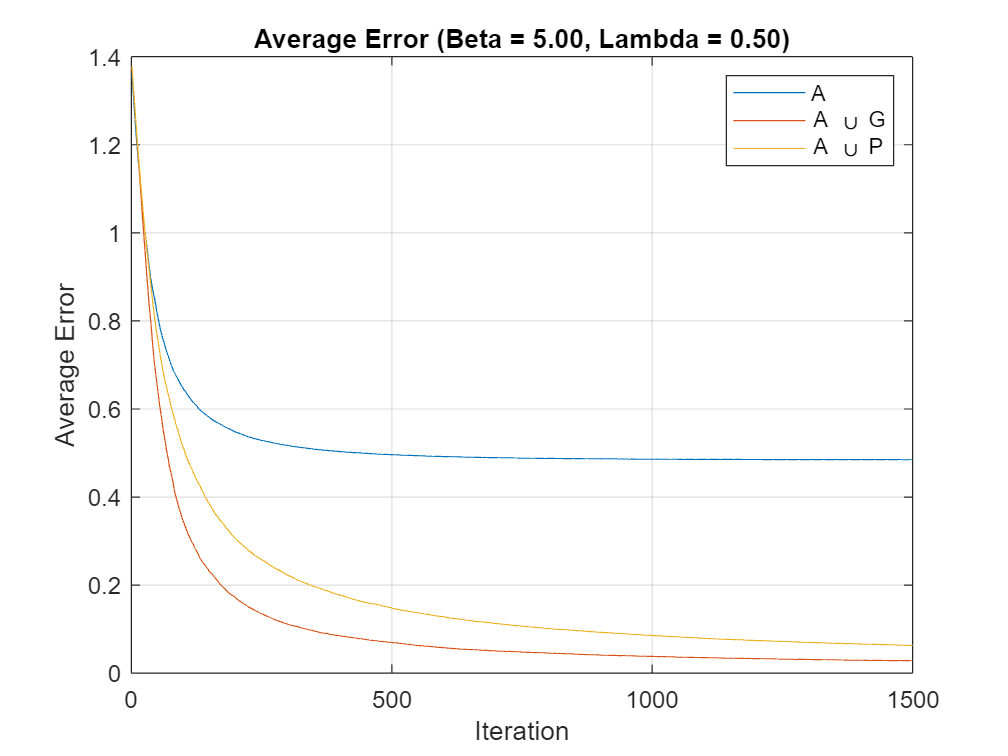

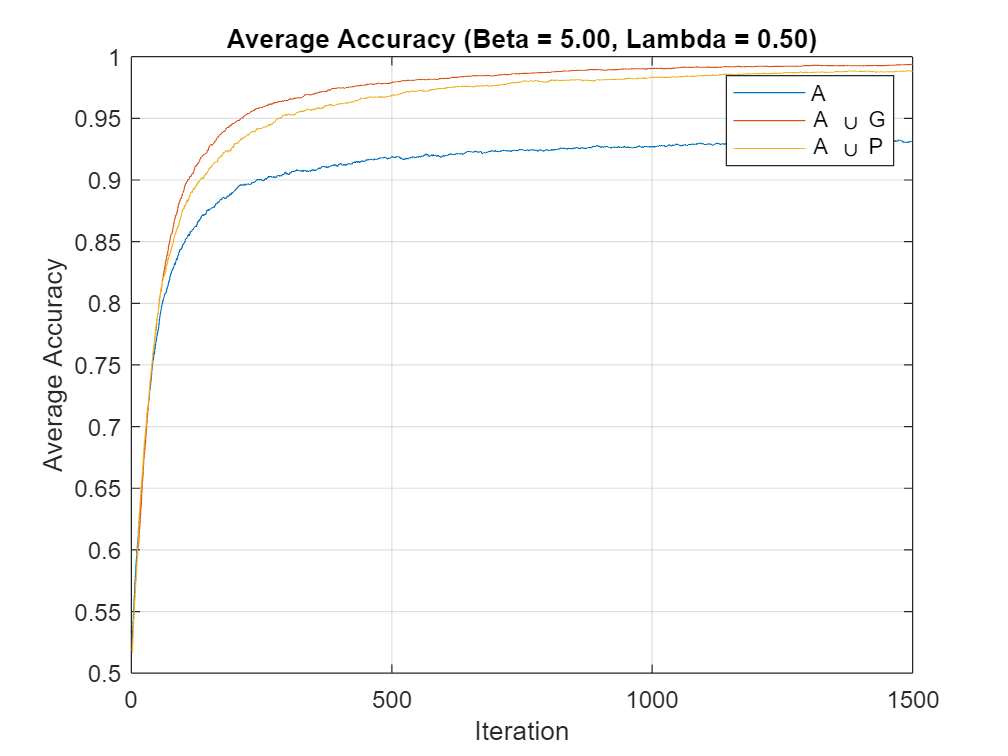

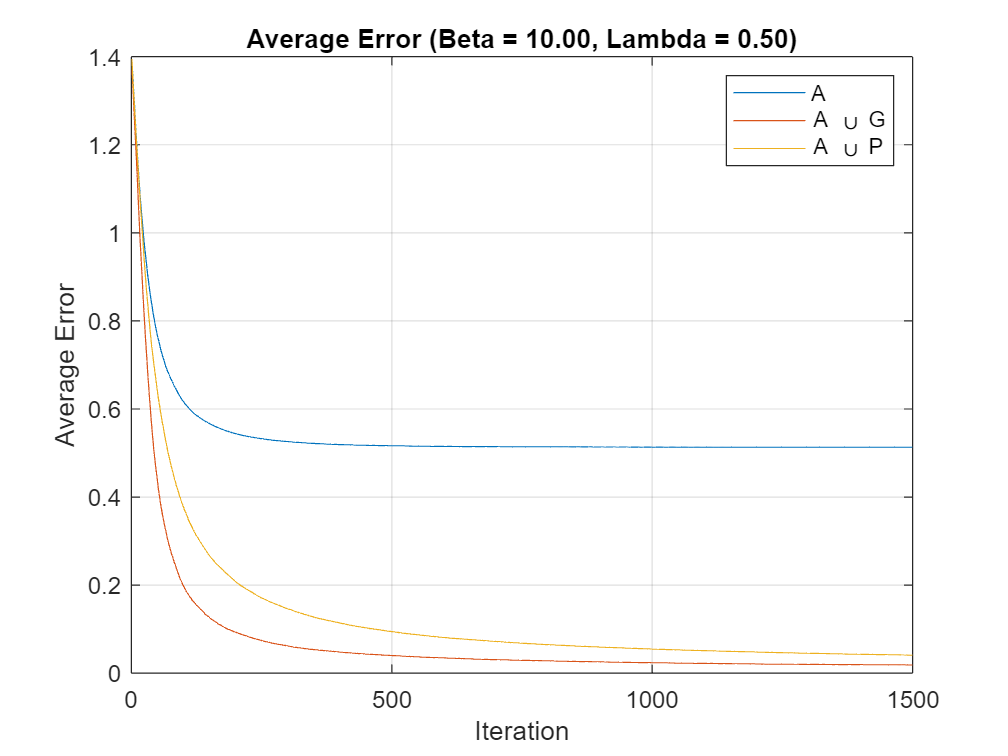

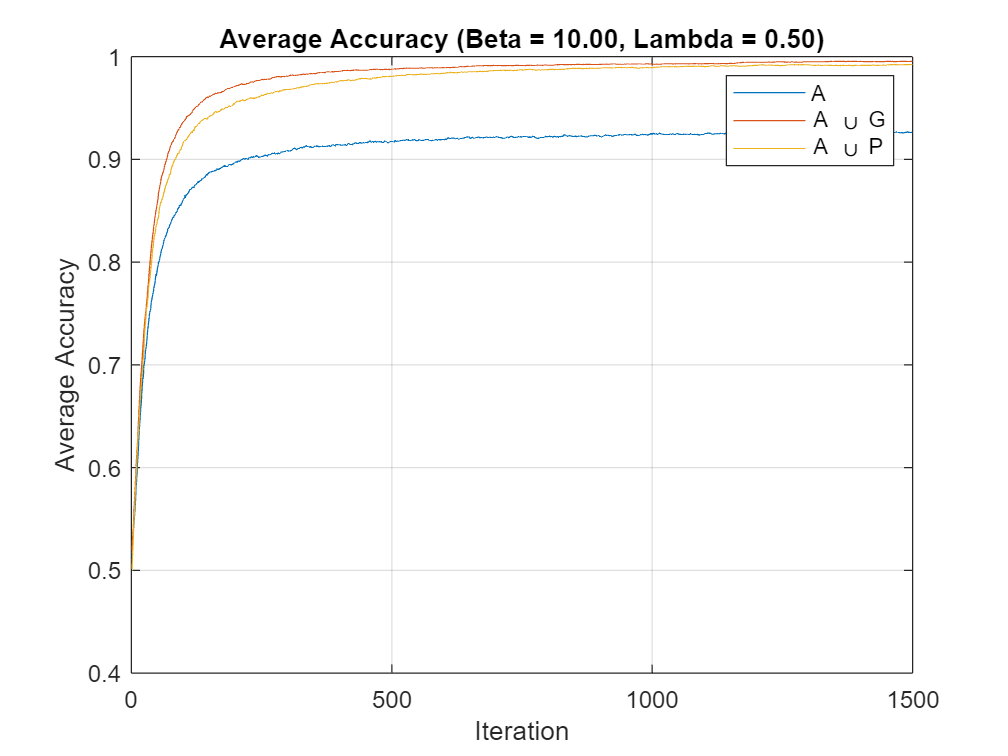

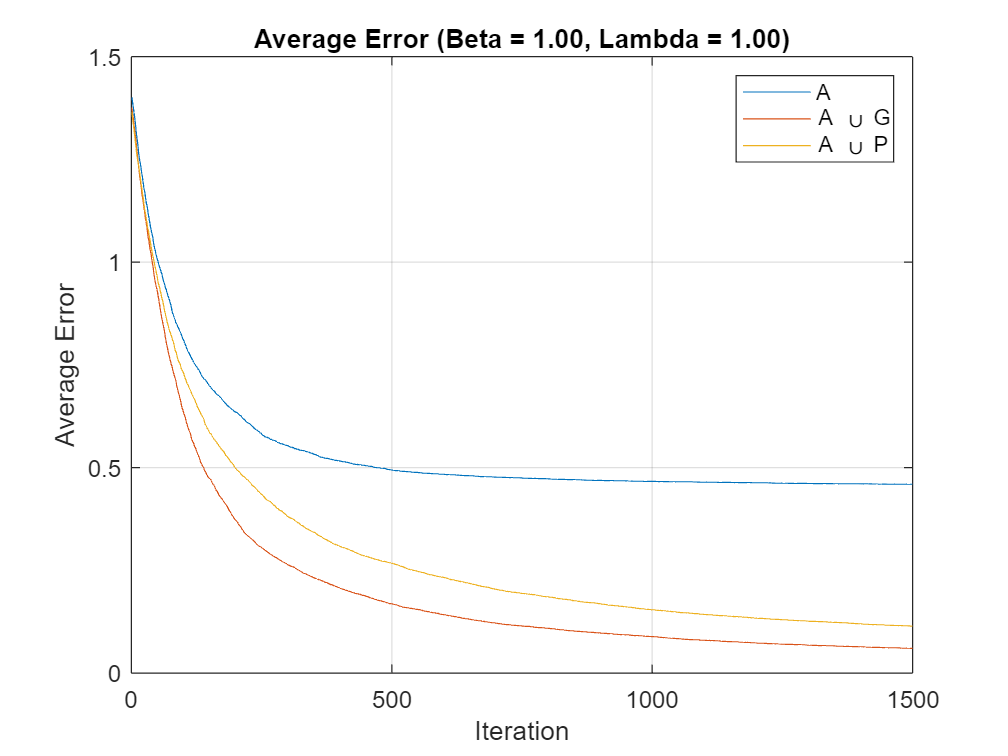

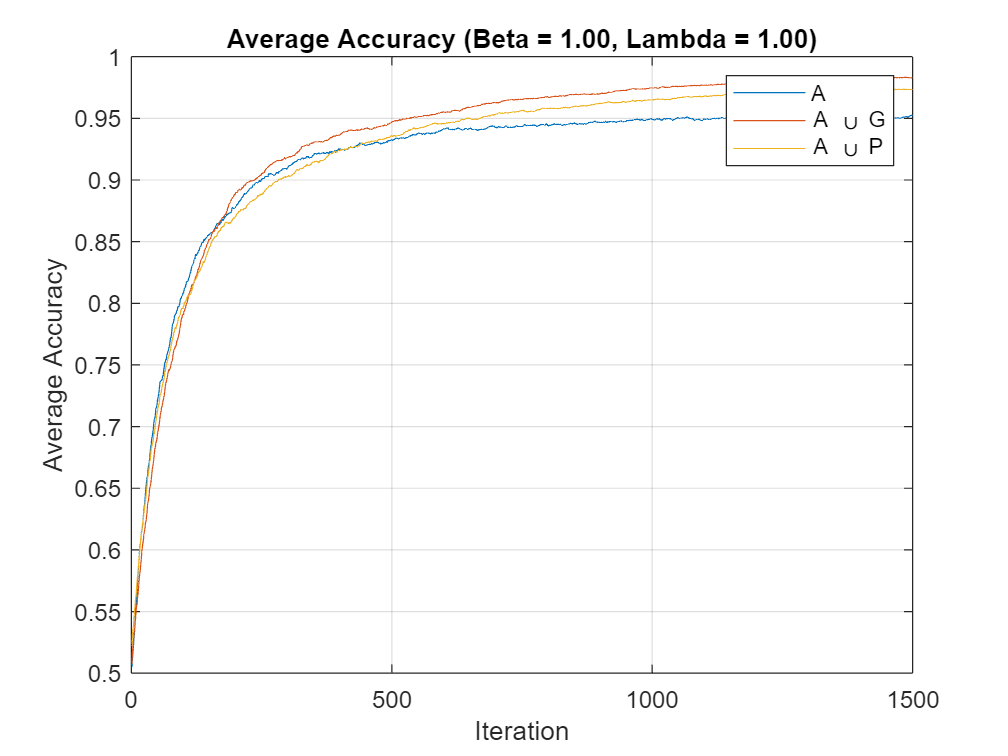

m = 100; n = 20;
A = randn(m, n);
A_prime = CombinedSampling(A, 'gaussian_promax');

beta = 1; lambda = 1.5; max_iter = 1500; num_original_rows = m; 
%[err, acc] = hadamardSKM(A_prime, beta, lambda, max_iter, num_original_rows);

num_trials = 100;
lambdas = [0.5, 1, 1.5];
betas = [1, 5, 10];

% Create parameter grid
[beta_grid, lambda_grid] = ndgrid(betas, lambdas);
parameter_combinations = [beta_grid(:), lambda_grid(:)];
num_combinations = size(parameter_combinations, 1);

% Initialize error and accuracy matrices
errMat_gaussian = zeros(num_trials, max_iter, num_combinations);
accMat_gaussian = zeros(num_trials, max_iter, num_combinations);

errMat_promax = zeros(num_trials, max_iter, num_combinations);
accMat_promax = zeros(num_trials, max_iter, num_combinations);

errMat_plus_pairwise = zeros(num_trials, max_iter, num_combinations);
accMat_plus_pairwise = zeros(num_trials, max_iter, num_combinations);

% Loop over parameter combinations

for combo_idx = 1:num_combinations
    beta = parameter_combinations(combo_idx, 1);
    lambda = parameter_combinations(combo_idx, 2);

    % Perform trials for the current parameter combination
    for trial = 1:num_trials
        % Generate random matrices
        A = randn(m, n);
        A_promax = CombinedSampling(A, 'gaussian_promax');
        A_plus_pairwise = CombinedSampling(A, 'gaussian_plus_pairwise');

        % Run HadamardSKM for each matrix
        [err_gaussian, acc_gaussian] = HadamardSKM(A, beta, lambda, max_iter, m);
        [err_promax, acc_promax] = HadamardSKM(A_promax, beta, lambda, max_iter, m);
        [err_plus_pairwise, acc_plus_pairwise] = HadamardSKM(A_plus_pairwise, beta, lambda, max_iter, m);

        % Store results
        errMat_gaussian(trial, :, combo_idx) = err_gaussian;
        accMat_gaussian(trial, :, combo_idx) = acc_gaussian;

        errMat_promax(trial, :, combo_idx) = err_promax;
        accMat_promax(trial, :, combo_idx) = acc_promax;

        errMat_plus_pairwise(trial, :, combo_idx) = err_plus_pairwise;
        accMat_plus_pairwise(trial, :, combo_idx) = acc_plus_pairwise;
    end
end

% Plotting
for combo_idx = 1:num_combinations
    beta = parameter_combinations(combo_idx, 1);
    lambda = parameter_combinations(combo_idx, 2);

    % Compute average error and accuracy over trials
    avg_err_gaussian = mean(errMat_gaussian(:, :, combo_idx), 1);
    avg_acc_gaussian = mean(accMat_gaussian(:, :, combo_idx), 1);

    avg_err_promax = mean(errMat_promax(:, :, combo_idx), 1);
    avg_acc_promax = mean(accMat_promax(:, :, combo_idx), 1);

    avg_err_plus_pairwise = mean(errMat_plus_pairwise(:, :, combo_idx), 1);
    avg_acc_plus_pairwise = mean(accMat_plus_pairwise(:, :, combo_idx), 1);

    % Plot average error for all methods
    figure;
    plot(1:max_iter, avg_err_gaussian, 'DisplayName', 'A');
    hold on;
    plot(1:max_iter, avg_err_promax, 'DisplayName', 'A \cup G');
    plot(1:max_iter, avg_err_plus_pairwise, 'DisplayName', 'A \cup P');
    hold off;
    xlabel('Iteration');
    ylabel('Average Error');
    title(sprintf('Average Error (Beta = %.2f, Lambda = %.2f)', beta, lambda));
    legend;
    grid on;

    % Plot average accuracy for all methods
    figure;
    plot(1:max_iter, avg_acc_gaussian, 'DisplayName', 'A');
    hold on;
    plot(1:max_iter, avg_acc_promax, 'DisplayName', 'A \cup G');
    plot(1:max_iter, avg_acc_plus_pairwise, 'DisplayName', 'A \cup P');
    hold off;
    xlabel('Iteration');
    ylabel('Average Accuracy');
    title(sprintf('Average Accuracy (Beta = %.2f, Lambda = %.2f)', beta, lambda));
    legend;
    grid on;
end

[err, acc] = HadamardSKM(A_prime, 10, 1, max_iter, num_original_rows);
err
acc

function [vec] = biSign(vec)
    vec = sign(vec);
    vec(vec == 0) = -1;
end

function mat_norm = stdMatrix(mat)
        row_norms = sqrt(sum(mat.^2, 2));
        mat_norm = mat ./ row_norms;
end

function [newMat] = CombinedSampling(A, type)
    valid_types = {'gaussian', 'gaussian_promax', 'gaussian_plus_pairwise'};
    if ~ismember(type, valid_types)
        error("Invalid type. Choose from 'gaussian', 'gaussian_promax', or 'gaussian_plus_pairwise'.");
    end

    [m, n] = size(A);

    if strcmp(type, 'gaussian')
        newMat = A;

    elseif strcmp(type, 'gaussian_promax')
        G = randn([nchoosek(m, 2), n]); 
        newMat = [A; G];

    elseif strcmp(type, 'gaussian_plus_pairwise')
        num_pairs = nchoosek(m, 2);
        P = zeros(num_pairs, n);
        
        count = 1;
        for i = 1:m-1
            for j = i+1:m
                P(count, :) = stdMatrix(A(i, :) - A(j, :)); 
                count = count + 1;
            end
        end
        
        newMat = [A; P];
    end
end

function [err, acc] = HadamardSKM(A, beta, lambda, max_iter, num_original_rows)

        [m, n] = size(A);
        A = stdMatrix(A);

        xstar = unifrnd(-1,1,[n 1]); % generate solution vector
            xstar = xstar / norm(xstar); % standardize solution vector
        xk = unifrnd(-1, 1, [n 1]); % generate initial iteration vector
            xk = xk / norm(xk); % standardize initial iteration vector
        
        b = biSign(A * xstar); % extract consistent comparison vector
        B = repmat(b, [1 n]); % create array with columns b

        H = -1 * A .* B; % apply hadamard transformation
        
        err = zeros([max_iter, 1]); acc = zeros([max_iter, 1]); % initialize columns for result matrix

        for k = 1:max_iter
                betas = randperm(m, beta); % select random indices
                rows = H(betas,:); % index by randomly selected indices
                residuals = rows * xk; % - b' % In this case, b' is the zero vector, since we perform the hadamard transformation to scale A
                
                res_max = max(residuals(residuals > 0)); % find the greatest positive residual

                if ~isempty(res_max) && res_max(1) > 0
                        row_max = rows(residuals == res_max, :); % find the row the maximizes the residual
    
                        xk = xk - lambda * res_max / norm(row_max) * row_max(1,:)'; % update iteration vector
                        xk = xk / norm(xk); % standardize iteration vector
                end
                err(k) = norm(xk - xstar)';
                acc(k) = mean(b(1:num_original_rows) == biSign(A(1:num_original_rows,:) * xk))';
        end
end